Нам дана задача о наискорейшем приведении в меридиан гироскопического компаса. В задаче даны матрицы А и В, которые указаны ниже:

A = [0 -1.53921/41.1368 -1.53921/41.1368*0.62;
     41.1368*10^-6 0 0;
     0 -1.5*10^-3 -1.5*10^-3];
B = [1;0;0];
X0 = [0.3; 0.01; 0.01];
A

A =          0   -0.0374   -0.0232
    0.0000         0         0
         0   -0.0015   -0.0015


B

B =      1
     0
     0


 Нам также дано ограничение на управление:


$$|u\left(t\right)|\le 0,6401\cdot {10}^{-3}$$


В связи с этим выполним нормировку следующего вида:

$\overset{\_}{u} \left(t\right)=\frac{1}{0,6401*{10}^{-3} }u\left(t\right)$, 

тогда матрица В примет вид:

B = B*0.6401*10^-3;
B

B = 	1.0e+-3 *

    0.6401
         0
         0


В нашей задаче мы хотим минимизировать функционал

$J\left(u\right)=\frac{1}{2}\int_0^{\infty } \left(u,u\right)\textrm{dt}\to \min$, который по сути означает минимизирование времени.

Приступим к анализу. 

Проверим устойчивость разомкнутой системы


$$\overset{\cdot }{X\;} =A\cdot X$$


Для этого найдем собственные числа матрицы А:

eig(A)

ans = 	1.0e+-3 *

  -0.3088 + 0.9481i
  -0.3088 - 0.9481i
  -0.8824 + 0.0000i


Полученные собственные числа имеют отрицательную вещественную часть, поэтому **размокнутая система устойчива**.

Теперь проверим управляемость системы:

G = [B A*B A^2*B];
if rank(G) ~= 3
    display('Система неуправляема');
else
    display('Ситема управляема');
end

Ситема управляема


Таким образом **система управляема**.

Теперь синтезируем линейно-квадратичный регулятор.

Введём параметры для системы

C = [0 0 0; 0 0 0];
D = [0; 0];
inputs = {'u'};
outputs = {'x' 'o'};
t = 0:10:2000; %в оригинальном тексте приводится решение для t_max < 2040
r = zeros(size(t)); %возмущения

Положим Q = 100*I, R = 1 (80)

Q = [100 0 0;
    0 100 0;
    0 0 100]

Q =    100     0     0
     0   100     0
     0     0   100


R = 30;
K = lqr(A,B,Q,R)

K =     9.8534  -22.6465  -26.7663


Попробуем

Ak = A-B*K

Ak =    -0.0063   -0.0229   -0.0061
    0.0000         0         0
         0   -0.0015   -0.0015


sys = ss(Ak, B, C, D, 'inputname', inputs, 'outputname', outputs);
[y,t,x] = lsim(sys, r, t, X0);
x

x =     0.3000    0.0100    0.0100
    0.2788    0.0101    0.0097
    0.2590    0.0102    0.0094
    0.2403    0.0103    0.0091
    0.2228    0.0104    0.0088
    0.2063    0.0105    0.0085
    0.1909    0.0106    0.0083
    0.1764    0.0107    0.0080
    0.1628    0.0107    0.0077
    0.1500    0.0108    0.0074


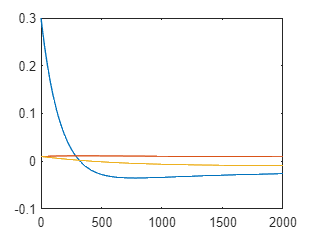

plot(t, x(:,1))
hold on
plot(t, x(:,2))
plot(t, x(:,3))
hold off

Попробуем ускорить процесс и добавить больший штраф за управление, положив R = 10:

R = 10

R = 10

K = lqr(A,B,Q,R)

K =     2.8352  -15.2620  -15.7077


Ak = A-B*K

Ak =    -0.0018   -0.0276   -0.0131
    0.0000         0         0
         0   -0.0015   -0.0015


sys = ss(Ak, B, C, D, 'inputname', inputs, 'outputname', outputs);
[y,t,x] = lsim(sys, r, t, X0);
x

x =     0.3000    0.0100    0.0100
    0.2906    0.0101    0.0097
    0.2813    0.0102    0.0094
    0.2722    0.0104    0.0091
    0.2633    0.0105    0.0088
    0.2546    0.0106    0.0085
    0.2460    0.0107    0.0082
    0.2376    0.0108    0.0080
    0.2293    0.0109    0.0077
    0.2212    0.0110    0.0074


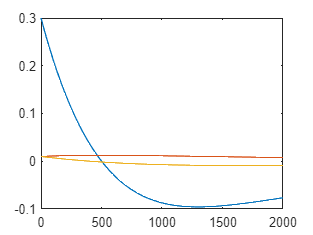

plot(t, x(:,1))
hold on
plot(t, x(:,2))
plot(t, x(:,3))
hold off

Кажется в этом случае система стремится наоборот держать управление около 0. Поробуем увеличить штраф за отклонение положив Q = 1000*I

Q = 1000*eye(3);
R = 1;
K = lqr(A,B,Q,R)

K =    31.6119   -5.3736  -33.0949


Ak = A-B*K

Ak =    -0.0202   -0.0340   -0.0020
    0.0000         0         0
         0   -0.0015   -0.0015


x =     0.3000    0.0100    0.0100
    0.2418    0.0101    0.0097
    0.1942    0.0102    0.0094
    0.1553    0.0103    0.0091
    0.1235    0.0103    0.0088
    0.0975    0.0104    0.0085
    0.0763    0.0104    0.0083
    0.0590    0.0104    0.0080
    0.0448    0.0105    0.0077
    0.0333    0.0105    0.0074


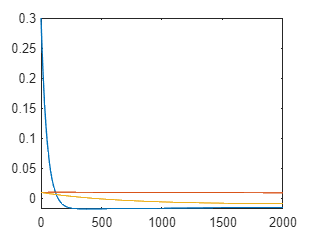

sys = ss(Ak, B, C, D, 'inputname', inputs, 'outputname', outputs);
[y,t,x] = lsim(sys, r, t, X0);
x

plot(t, x(:,1))
hold on
plot(t, x(:,2))
plot(t, x(:,3))
hold off

Наибольшее отклонение от целевого значния дает именно первая переменная. Попробуем увеличить штраф за отклонение у нее, оставив штрафы у остальных переменных равными единице

Q = [100 0 0;
    0 1 0;
    0 0 1];
R = 1;
K = lqr(A,B,Q,R)

K =     9.8281  -26.5177  -26.5627


Ak = A-B*K

Ak =    -0.0063   -0.0204   -0.0062
    0.0000         0         0
         0   -0.0015   -0.0015


sys = ss(Ak, B, C, D, 'inputname', inputs, 'outputname', outputs);
[y,t,x] = lsim(sys, r, t, X0);
x

x =     0.3000    0.0100    0.0100
    0.2791    0.0101    0.0097
    0.2595    0.0102    0.0094
    0.2411    0.0103    0.0091
    0.2238    0.0104    0.0088
    0.2076    0.0105    0.0085
    0.1923    0.0106    0.0083
    0.1780    0.0107    0.0080
    0.1645    0.0107    0.0077
    0.1519    0.0108    0.0074


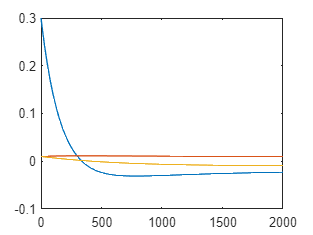

plot(t, x(:,1))
hold on
plot(t, x(:,2))
plot(t, x(:,3))
hold off

Видно, что это привело к гораздо более быстрой сходимости. Посмотрим на большем временном интервале:

t = 0:10:10000; %в оригинальном тексте приводится решение для t_max < 2040
r = zeros(size(t)); %возмущения
[y,t,x] = lsim(sys, r, t, X0);
x

x =     0.3000    0.0100    0.0100
    0.2791    0.0101    0.0097
    0.2595    0.0102    0.0094
    0.2411    0.0103    0.0091
    0.2238    0.0104    0.0088
    0.2076    0.0105    0.0085
    0.1923    0.0106    0.0083
    0.1780    0.0107    0.0080
    0.1645    0.0107    0.0077
    0.1519    0.0108    0.0074


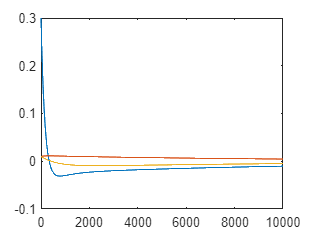

plot(t, x(:,1))
hold on
plot(t, x(:,2))
plot(t, x(:,3))
hold off

Видно, что затухание колебаний замедляется со временем, и уже после 2-3 тыс. с становится почти незаметной.

Зададим вектор выхода системы произвольным образом:

C = [1 0.5 0.3;
    0.7 2 0.4;
    0 1 1];
H = [C.'; A.'*C.'; (A.')^2*C.'];
if rank(G) ~= 3
    display('Система ненаблюдаема');
else
    display('Ситема наблюдаема');
end

Ситема наблюдаема


Теперь сконструируем полного наблюдателя, для этого необходимо найти матрицу L. Матрицу L выберем исходя из формального равила, что собственные числа A-LC должны быть на порядок больше с.з. A-BK:

%Используем K с предыдущего шага
eigen_values = eig(Ak)

eigen_values =    -0.0061
   -0.0001
   -0.0016


L = place(A.', C.', 10*eigen_values).'

L =     0.0741   -0.0182   -0.0382
   -0.0004    0.0006   -0.0001
    0.0075   -0.0107    0.0161


Aobs = [A-B*K B*K;
    zeros(size(A)) A-L*C]

Aobs =    -0.0063   -0.0204   -0.0062    0.0063   -0.0170   -0.0170
    0.0000         0         0         0         0         0
         0   -0.0015   -0.0015         0         0         0
         0         0         0   -0.0614   -0.0000    0.0000
         0         0         0    0.0000   -0.0009   -0.0000
         0         0         0   -0.0000    0.0000   -0.0156


Bobs = [B; zeros(size(B))]

Bobs = 	1.0e+-3 *

    0.6401
         0
         0
         0
         0
         0


Cobs = [C zeros(size(C))]

Cobs =     1.0000    0.5000    0.3000         0         0         0
    0.7000    2.0000    0.4000         0         0         0
         0    1.0000    1.0000         0         0         0


Dobs = [0;0;0]

Dobs =      0
     0
     0


sys_obs = ss(Aobs, Bobs, Cobs, Dobs);
t = 0:10:2000; %в оригинальном тексте приводится решение для t_max < 2040
r = zeros(size(t)); %возмущения
X0obs = [X0; C*X0];
[y,t,x] = lsim(sys_obs, r, t, X0obs);
x

x =     0.3000    0.0100    0.0100    0.3080    0.2340    0.0200
    0.2517    0.0101    0.0097    0.1667    0.2319    0.0171
    0.2008    0.0102    0.0094    0.0902    0.2297    0.0146
    0.1502    0.0103    0.0091    0.0488    0.2276    0.0125
    0.1015    0.0103    0.0088    0.0264    0.2256    0.0107
    0.0554    0.0104    0.0085    0.0143    0.2235    0.0092
    0.0121    0.0104    0.0083    0.0077    0.2215    0.0079
   -0.0283    0.0104    0.0080    0.0042    0.2194    0.0067
   -0.0659    0.0104    0.0077    0.0023    0.2174    0.0057
   -0.1007    0.0103    0.0074    0.0012    0.2154    0.0049


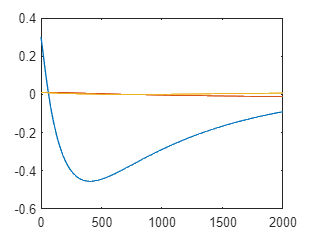

plot(t, x(:,1))
hold on
plot(t, x(:,2))
plot(t, x(:,3))
hold off

Проверим другие условия

Q = [100 0 0;
    0 100 0;
    0 0 100];
R = 1;
K = lqr(A,B,Q,R);
Ak = A-B*K;
eigen_values = eig(Ak);
L = place(A.', C.', 10*eigen_values).';
Aobs = [A-B*K B*K;
    zeros(size(A)) A-L*C];
sys_obs = ss(Aobs, Bobs, Cobs, Dobs);
[y,t,x] = lsim(sys_obs, r, t, X0obs);
x

x =     0.3000    0.0100    0.0100    0.3080    0.2340    0.0200
    0.2571    0.0101    0.0097    0.1667    0.2315    0.0171
    0.2112    0.0102    0.0094    0.0902    0.2290    0.0146
    0.1653    0.0103    0.0091    0.0488    0.2265    0.0125
    0.1211    0.0103    0.0088    0.0264    0.2240    0.0107
    0.0791    0.0104    0.0085    0.0143    0.2216    0.0092
    0.0397    0.0104    0.0083    0.0077    0.2192    0.0079
    0.0030    0.0104    0.0080    0.0042    0.2169    0.0067
   -0.0311    0.0104    0.0077    0.0023    0.2145    0.0058
   -0.0627    0.0104    0.0074    0.0012    0.2122    0.0049


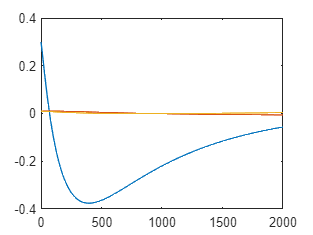

plot(t, x(:,1))
hold on
plot(t, x(:,2))
plot(t, x(:,3))
hold off

и ещё

Q = 1000*eye(3);
R = 1;
K = lqr(A,B,Q,R);
Ak = A-B*K;
eigen_values = eig(Ak);
L = place(A.', C.', 10*eigen_values).';
Aobs = [A-B*K B*K;
    zeros(size(A)) A-L*C];
sys_obs = ss(Aobs, Bobs, Cobs, Dobs);
[y,t,x] = lsim(sys_obs, r, t, X0obs);
x

x =     0.3000    0.0100    0.0100    0.3080    0.2340    0.0200
    0.2544    0.0101    0.0097    0.0410    0.2325    0.0172
    0.1974    0.0102    0.0094    0.0055    0.2310    0.0148
    0.1485    0.0103    0.0091    0.0007    0.2295    0.0127
    0.1087    0.0103    0.0088    0.0001    0.2280    0.0110
    0.0764    0.0104    0.0085    0.0000    0.2265    0.0094
    0.0503    0.0104    0.0083    0.0000    0.2250    0.0081
    0.0294    0.0104    0.0080    0.0000    0.2236    0.0070
    0.0125    0.0104    0.0077    0.0000    0.2221    0.0060
   -0.0011    0.0104    0.0074    0.0000    0.2207    0.0052


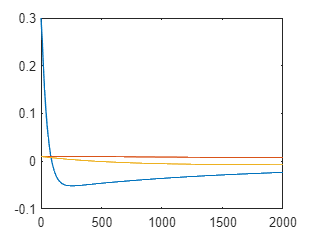

plot(t, x(:,1))
hold on
plot(t, x(:,2))
plot(t, x(:,3))
hold off